sorted_dir = '/mnt/40086D4C086D41D0/Inhibitory_excitatory_analysis/For_analysis/Ronnie/P05/P05-quning';
save_dir = '/mnt/40086D4C086D41D0/Inhibitory_excitatory_analysis/For_analysis/Ronnie/P05/P05-quning/Plots/Test_Plots';

%% Define params
font_axis = 12; %Font size for plotting
upsamp_factor = 100; %How many times to upsample the wfs for feature extraction
method = 'makima'; %Which method to use for itnerpolation 
%% Load and name
file_path = fullfile(sorted_dir,'clust_info.mat');
load(file_path);
slash_ix1 = find(file_path == '/', 1, 'last');
var_name = file_path(slash_ix1+1:end);
var_name = strrep(var_name,'_',' ');
%% Get waveforms and interpolate
ix_good_wfs = clust_info.good_units(:,2);
good_wfs = clust_info.mean_wfs(ix_good_wfs,:); %Use only waveforms that come from single units
good_wfs(16,:) = []; %Temporary hack !!!!!!!!!!!!!!!! I have a problem wiht funky waveform
wf_time = clust_info.wf_time;
[int_wf,int_time_ms] = interpolate_wf(good_wfs,wf_time,upsamp_factor,method);
%% Extract feature
int_wf = int_wf.*clust_info.scaleToUv; %Convert the y-scale to uV
[results] = feature_extract(int_wf,int_time_ms);


Perform PCA on the covariance matrix of neuronal firing rates

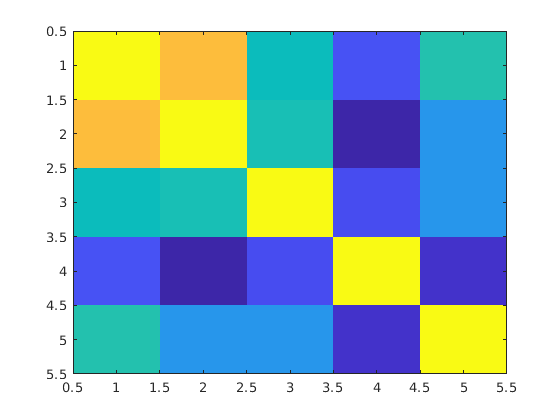

X_fw = [results.spike_width_ms,results.width_hh_trough_ms,results.end_slope,results.peak_trough_ratio,results.width_hh_peak_ms];
X_fw = X_fw';
mean_X_f = mean(X_fw,2);
std_X_f = std(X_fw,[],2);
norm_X_fw = (X_fw - mean_X_f)./std_X_f;
C = cov(norm_X_fw');
figure;
imagesc(C);

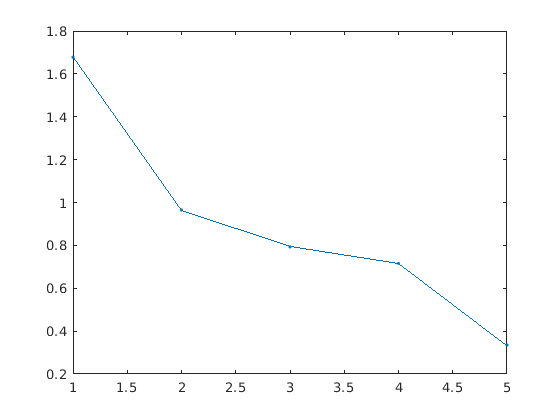

[U,D] = eig(C);
U = fliplr(U);
lambda = diag(D);
lambda = flipud(lambda);
var_total = sum(lambda);
norm_lambda = lambda/var_total;
cum_lambda = cumsum(norm_lambda);
sqrt_lambda = sqrt(lambda);
figure;
plot(sqrt_lambda,'.-');

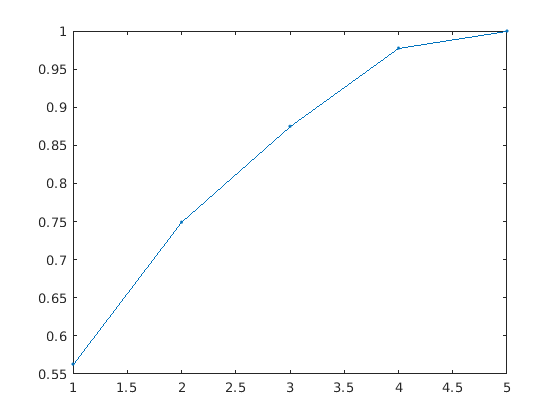

figure;
plot(cum_lambda,'.-');

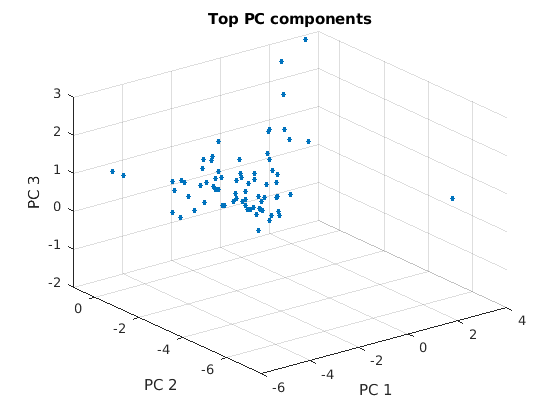


first_PCcomp = 1;
last_PCcomp = 3;
T = size(X_fw,2);
D = size(X_fw,1);
Z = U(:,first_PCcomp:last_PCcomp)'*norm_X_fw;
figure;
scatter3(Z(1,:),Z(2,:),Z(3,:),14,'filled');
title('Top PC components');
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

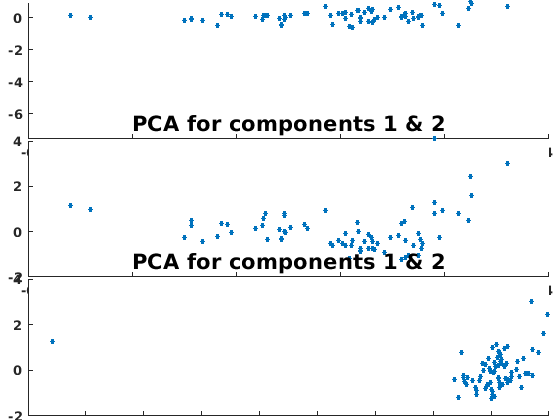


num_columns = 1;
num_rows = 3;
per = 0.005;
edgel = 0.05; edger = 0.02; edgeh = per; edgeb = 0.01; space_h = 0.05; space_v = per;
[pos]=subplot_pos(num_rows,num_columns,edgel,edger,edgeh,edgeb,space_h,space_v);


figure;
subplot('position',pos{1});
hold on;
scatter(Z(1,:),Z(2,:),14,'filled');
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC1','FontSize',16,'FontWeight','bold');
ylabel('PC2','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;


subplot('position',pos{2});
hold on;
scatter(Z(1,:),Z(3,:),14,'filled');
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC1','FontSize',16,'FontWeight','bold');
ylabel('PC3','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;

subplot('position',pos{3});
hold on;
scatter(Z(2,:),Z(3,:),14,'filled');
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC2','FontSize',16,'FontWeight','bold');
ylabel('PC3','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;

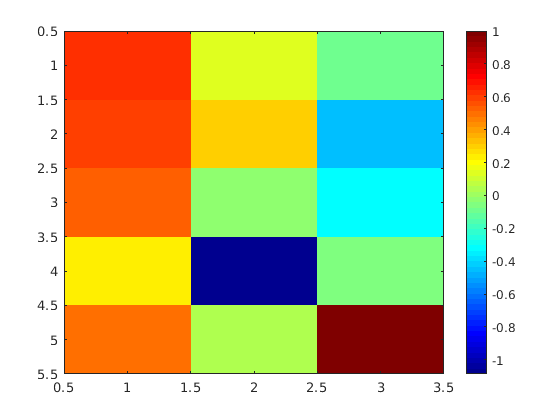


U_m = U(:,first_PCcomp:last_PCcomp);
figure;
max_U = max(U_m(:));
imagesc(U_m./max_U);
colormap(jet);
colorbar;

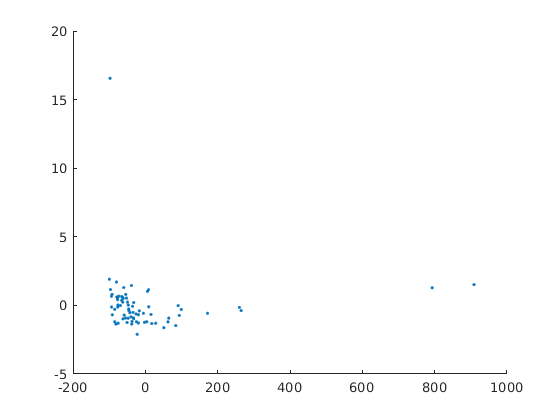


%Multidimensional scaling 

test = pdist(X_fw');
cmd_test = cmdscale(test,2);
figure;
hold on; 
plot(cmd_test(:,1),cmd_test(:,2),'.');